clc
clear

data = load('data.mat');
data = data.data;

data_train = data(:, 1:2500)';
A = [data_train(:, 1).*data_train(:, 3), data_train(:, 2).*data_train(:, 3),...
    data_train(:, 3)];
A = -1*[A, eye(2500)];

f = [-1, 1, 0, 1*ones(1, 2500)];

[xx, fval, exitflag, output, lambda] = linprog(f, A, -1*ones(1, 2500), [], [],...
    [-inf, -inf, -inf, zeros(1, 2500)])


Optimal solution found.



xx =    -0.0445
    0.2744
   -0.5029
         0
         0
    0.4102
         0
         0
    0.5740
         0


fval = 475.8236

exitflag = 1

output = struct with fields:
         iterations: 632
    constrviolation: 9.9920e-16
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 4.2633e-14


lambda = struct with fields:
      lower: [2503×1 double]
      upper: [2503×1 double]
      eqlin: []
    ineqlin: [2500×1 double]


w1 = xx(1);
w2 = xx(2);
b = xx(3);

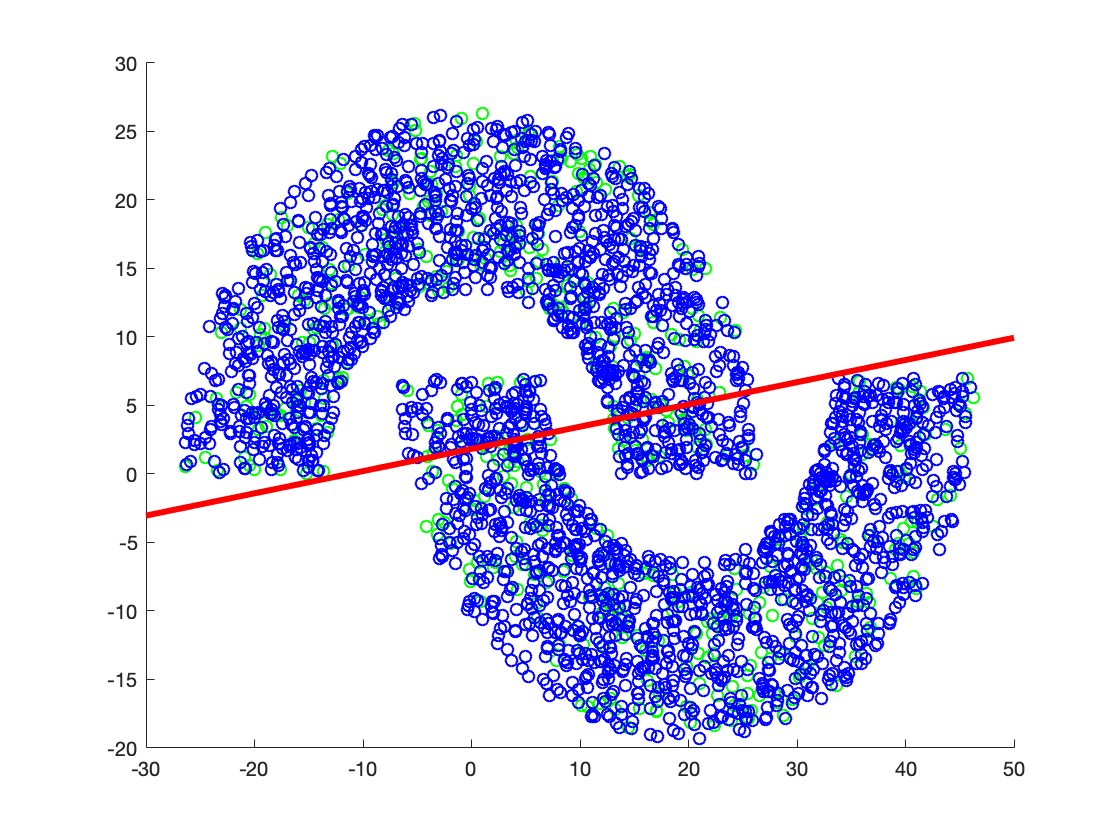

syms y(x)
y(x) =  x * -1 * w1/w2 - b/w2;
scatter(data(1,2501:3000), data(2,2501:3000), [], 'green')
hold on
scatter(data(1,1:2500), data(2,1:2500), [], 'blue')
plot(-30:1:50, y(-30:1:50), 'r', 'LineWidth',3)